%Assignment for Manastu space
clc;
clear;

%All variables and parameters are calculated in standard SI unit
% Variables
mu = 398600; %Standard gravitational parameter km3/s2
earthRadius = 6371; %km
orbitHeight = 600; %km
meanMotion = sqrt(mu/(earthRadius+orbitHeight)^3); % rad/s
massChaser = 2; %kg
gravity = 9.8; %m/s2
dryMass = 3 ; % kg
fuelMass = 1; %kg
totalMass = dryMass+fuelMass;
massFlow = 0.01; %kg/s for a monopropellant spacecraft

Assignment of initial conditions and constraints

% Time constraint
dt = 10; %sec
totalTime = 3*3600; % 3 hours
timesteps = totalTime/dt;

% LVLH Reference frame = RTN reference frame for a circular orbit
% Initial conditions
initialPosTarget = [0;0;0]; %Radial, tangential and normal
initialPosChaser = [0;-5000;0]; % chaser is 5000 m behind the target
initialVelChaser = [0;0;0];
initialThrust = [0;0;0];

%Terminal conditions of chaser
termPosition = [0;3;0]; % Can be a range between 1 to 5 m
termVelocity = [0;0.22;0];

% Assignment Array
posChaser = zeros(3,timesteps);
posChaser(:,1) = initialPosChaser;
velChaser = zeros(3,timesteps);
thrustChaser = zeros(3,timesteps);

%Boundary conditions / Constraints
maxThrust=10; % N
minDistanceDebris = 50; % m

%Fixed debris definition
posDebris1 = [0;100;0];
posDebris2 = [50;50;0];
posDebris3 = [0;3600;360];
posDebris4 = [0;2000;0];

Calculate fuel usage

specificImpulse = maxThrust/(massFlow*gravity); %sec

Predicting debris state (position and velocity)

clc;
clear all;
mu = 398600; %Standard gravitational parameter km3/s2
earthRadius = 6371; %km
orbitHeight = 600; %km
meanMotion = sqrt(mu/(earthRadius+orbitHeight)^3); % rad/s
%Implementing MPC
n=meanMotion;
% Discretize Hill's Equations (State-Space Model)
% Continuous-time system dynamics
A = [0, 0, 0, 1, 0, 0; 
     0, 0, 0, 0, 1, 0; 
     0, 0, 0, 0, 0, 1;
     3*n^2, 0, 0, 0, 2*n, 0;
     0, 0, 0, -2*n, 0, 0;
     0, 0, -n^2, 0, 0, 0];
B = [0, 0, 0; 
     0, 0, 0; 
     0, 0, 0; 
     1, 0, 0; 
     0, 1, 0; 
     0, 0, 1];
C = eye(6); % Full-state output
D = zeros(6, 3); 

% Discretization (use sample time Ts)
Ts = 10; % Sampling time (seconds)
sysc = ss(A, B, C, D); % Continuous-time state-space model
sysd = c2d(sysc, Ts); % Discrete-time state-space model
Ad = sysd.A;
Bd = sysd.B;

% Create the MPC Controller
mpc_controller = mpc(sysd, Ts,50,20);

-->The "Weights.ManipulatedVariables" property is empty. Assuming default 0.00000.
-->The "Weights.ManipulatedVariablesRate" property is empty. Assuming default 0.10000.
-->The "Weights.OutputVariables" property is empty. Assuming default 1.00000.
   for output(s) y1 y2 y3 and zero weight for output(s) y4 y5 y6 



% Define MPC Parameters
mpc_controller.PredictionHorizon = 50; % Predict 50 steps ahead
mpc_controller.ControlHorizon = 20;    % Optimize for 20 steps
mpc_controller.Weights.ManipulatedVariables = [1, 1, 1]; % Input effort
mpc_controller.Weights.ManipulatedVariablesRate = [0.1, 0.1, 0.1]; % Input change rate
mpc_controller.Weights.OutputVariables = [1, 1, 1, 0.5, 0.5, 0.5]; % State weights

% Input Constraints (e.g., thrust limits)
mpc_controller.ManipulatedVariables(1).Min = -1; % Thrust x min (km/s^2)
mpc_controller.ManipulatedVariables(1).Max = 1;  % Thrust x max (km/s^2)
mpc_controller.ManipulatedVariables(2).Min = -1; % Thrust y min (km/s^2)
mpc_controller.ManipulatedVariables(2).Max = 1;  % Thrust y max (km/s^2)
mpc_controller.ManipulatedVariables(3).Min = -1; % Thrust z min (km/s^2)
mpc_controller.ManipulatedVariables(3).Max = 1;  % Thrust z max (km/s^2)

% Simulation Parameters
x0 = [0; 5; 0; 0; 0; 0]; % Initial state (5 km behind target)
ref = [0; 0; 0; 0; 0; 0]; % Target position and velocity

%initialize the MPCSTATE object
mpc_state=mpcstate(mpc_controller);

-->Assuming output disturbance added to measured output channel #1 is integrated white noise.
   Assuming no disturbance added to measured output channel #2.
-->Assuming output disturbance added to measured output channel #3 is integrated white noise.
-->Assuming output disturbance added to measured output channel #4 is integrated white noise.
-->Assuming output disturbance added to measured output channel #5 is integrated white noise.
-->Assuming output disturbance added to measured output channel #6 is integrated white noise.
-->The "Model.Noise" property is empty. Assuming white noise on each measured output.


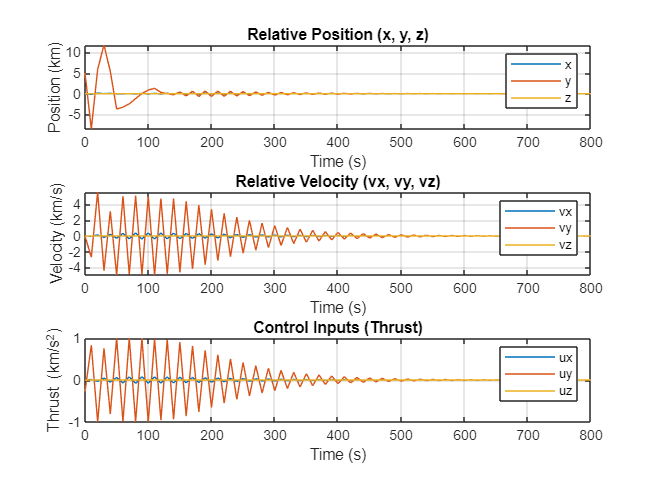


% Simulate Closed-Loop System
Tsim = 800; % Total simulation time
x = x0; % Initialize state
u_history = [];
x_history = x0';

for t = 0:Ts:Tsim
    % Compute MPC Control Action
    [u,mpcstate] = mpcmove(mpc_controller, mpc_state,x, ref);
    
    % Apply Control Action (Update State)
    x = Ad * x + Bd * u;
    
    % Log Data
    u_history = [u_history; u'];
    x_history = [x_history; x'];
end

% Correct time vector
time = 0:Ts:Tsim; % Time vector for simulation
time_x = 0:Ts:Tsim; % Matches the number of states recorded in x_history
x_history = x_history(1:length(time), :); % Trim x_history to match time vector
%u_history = u_history(1:length(time), :);

figure;
subplot(3, 1, 1);
plot(time_x, x_history(:, 1:3)); % Plot position (x, y, z)
title('Relative Position (x, y, z)');
xlabel('Time (s)');
ylabel('Position (km)');
legend('x', 'y', 'z');
grid on;

subplot(3, 1, 2);
plot(time_x, x_history(:, 4:6)); % Plot velocity (vx, vy, vz)
title('Relative Velocity (vx, vy, vz)');
xlabel('Time (s)');
ylabel('Velocity (km/s)');
legend('vx', 'vy', 'vz');
grid on;

subplot(3, 1, 3);
plot(time_x, u_history);
title('Control Inputs (Thrust)');
xlabel('Time (s)');
ylabel('Thrust (km/s^2)');
legend('ux', 'uy', 'uz');
grid on;

%function usedFuel = fuelUsage(initialFuel, deltaV,specificImpulse)
    %usedFuel = initialFuel(1-exp(-deltaV/(specificImpulse*9.8)));
%end

3D Visualisation

% 3D Visualisation
%{
epochYear = 2024;
epochMonth = 1;
epochDay = 7;
epochHour = 0;
epochMinute = 0;
epochSecond = 0;
epoch = datetime(epochYear,epochMonth,epochDay,epochHour,epochMinute,epochSecond);

starTime=epoch;
stopTime=starTime+seconds(Tsim);
sampleTime= 10;%seconds(stopTime-starTime/35311);
sc=satelliteScenario(starTime,stopTime,sampleTime);

%Extract information from the model
chaserPos = x_history(:,3); %simOut.yout{1}.Values;
targetPos = x_history(:,3) ; %simOut.yout{2}.Values;

%Add chaser and target spacecraft in the scenario
chaser = satellite(sc,chaserPos,'Name', 'Chaser');
pointAt(chaser,'nadir');
chaserDockingPort = conicalSection(chaser,MountingLocation=[0.5;0;0]);

target = satellite(sc,targetPos,'Name', 'Target');
pointAt(target,'nadir');
targetDockingPort = conicalSection(target,MountingLocation=[0.5;0;0]);

%Launch the satellite scenario viewer
v = satelliteScenarioViewer (sc,CameraReferenceFrame="Inertial");
chaser.Visual3DModel="SmallSat.glb";
chaser.Visual3DModelScale=0.8;
target.Visual3DModel="SmallSat.glb";
target.Visual3DModelScale=0.8;
coordinateAxes([chaser target],Scale=2);
hide(chaser.Orbit);
hide(target.Orbit);

play(sc);
camtarget(v,chaser); 
%}


so this

% 3D Visualization Setup
epochYear = 2024;
epochMonth = 1;
epochDay = 7;
epochHour = 0;
epochMinute = 0;
epochSecond = 0;
epoch = datetime(epochYear, epochMonth, epochDay, epochHour, epochMinute, epochSecond);

startTime = epoch;
stopTime = startTime + seconds(800);
sampleTime = 10; % seconds

semiMajorAxis = 7000000; % km
eccentricity = 0;
inclination = 0; % degrees
rightAscensionOfAscendingNode = 0; % degrees
argumentOfPeriapsis = 0; % degrees
trueAnomaly = 0; % degrees
%sat2 = satellite(sc,semiMajorAxis, ...
        %eccentricity, ...
        %inclination, ...
        %rightAscensionOfAscendingNode, ...
       % argumentOfPeriapsis, ...
        %trueAnomaly, ...
       % "OrbitPropagator","two-body-keplerian", ...
        %"Name","Sat2")
% Create the satellite scenario
sc = satelliteScenario(startTime, stopTime, sampleTime);

% Extract chaser and target positions from x_history
% Assuming x_history contains relative position of chaser
chaserPos = x_history(:, 1:3);  % Chaser relative position (x, y, z)
targetPos = [0, 0, 0];          % Target position assumed at origin (for simplicity)

% Add chaser satellite with orbital parameters (e.g., 700 km altitude)
chaser = satellite(sc,semiMajorAxis, eccentricity,inclination,rightAscensionOfAscendingNode,argumentOfPeriapsis,trueAnomaly,"OrbitPropagator","two-body-keplerian",'Name', 'Chaser'); % 700 km orbit altitude
pointAt(chaser, 'nadir');
%chaserDockingPort = conicalSection(chaser, 'MountingLocation', [0.5; 0; 0]);

% Add target satellite with orbital parameters (e.g., same orbit as chaser)
target = satellite(sc,semiMajorAxis, eccentricity,inclination,rightAscensionOfAscendingNode,argumentOfPeriapsis,trueAnomaly,"OrbitPropagator","two-body-keplerian",'Name', 'Target'); % 700 km orbit altitude
pointAt(target, 'nadir');
%targetDockingPort = conicalSection(target, 'MountingLocation', [0.5; 0; 0]);

% Launch the satellite scenario viewer
v = satelliteScenarioViewer(sc, 'CameraReferenceFrame', "Inertial");

% Set the 3D models for both satellites - upgrade matlab
%chaser.Visual3DModel = "SmallSat.glb";
%chaser.Visual3DModelScale = 0.8;
%target.Visual3DModel = "SmallSat.glb";
%target.Visual3DModelScale = 0.8;

% Display coordinate axes for both chaser and target
%coordinateAxes([chaser, target], 'Scale', 2);

Unrecognized function or variable 'coordinateAxes'.


% Hide the orbits to focus on the satellites' positions
hide(chaser.Orbit);
hide(target.Orbit);

% Now update the relative position of the chaser over time
for i = 1:length(x_history)
    % Update target position (assuming target is stationary for now)
    targetPos = [0, 0, 0];  % Target is at the origin in this example

    % Update chaser's position based on relative position data from x_history
    chaserPosition = targetPos + chaserPos(i, :);  % Chaser's new position relative to target

    % Update the chaser's position in the scenario (every timestep)
    chaser.Position = chaserPosition; 

    % Plot and play the scenario
    play(sc);
    pause(sampleTime);  % Simulate with a delay between each timestep
end

% Camera follows the chaser satellite
camtarget(v, chaser);

%Another try